# Sample 4-3

## 線形シフト不変システム

可分離フィルタ

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Linear shift-invariant systems

Separable filter

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### インパルス応答の生成

(Generation of impulse response)

ftype = "average";
h = rot90(fspecial(ftype),2)

h =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


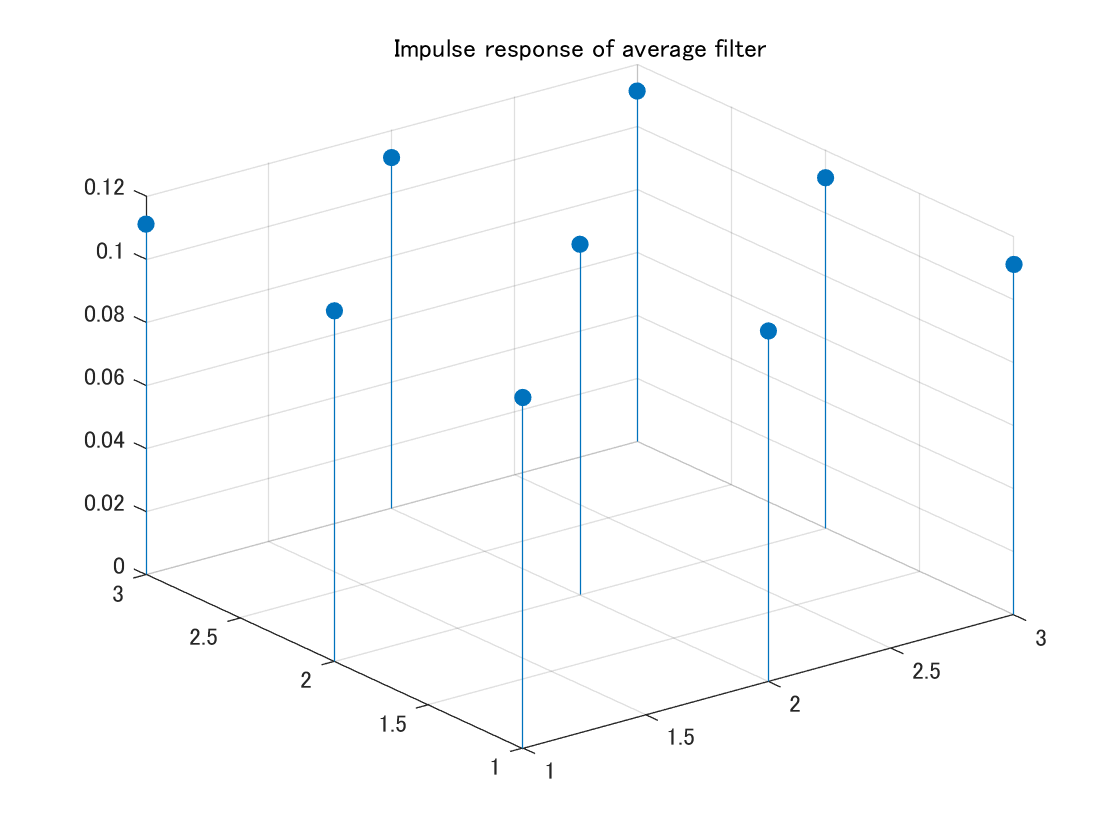

figure(1)
stem3(h,'filled')
title(['Impulse response of ' char(ftype) ' filter'])

### 可分離性の確認

(Checking the separability)

#### 関数ISFILTERSEPARABLEによる可分離性の確認

(Checking the separability using the function ISFILTERSEPARABLE)

h[n] is separable.


hcol: 


   -0.3333
   -0.3333
   -0.3333



hrow: 


   -0.3333   -0.3333   -0.3333



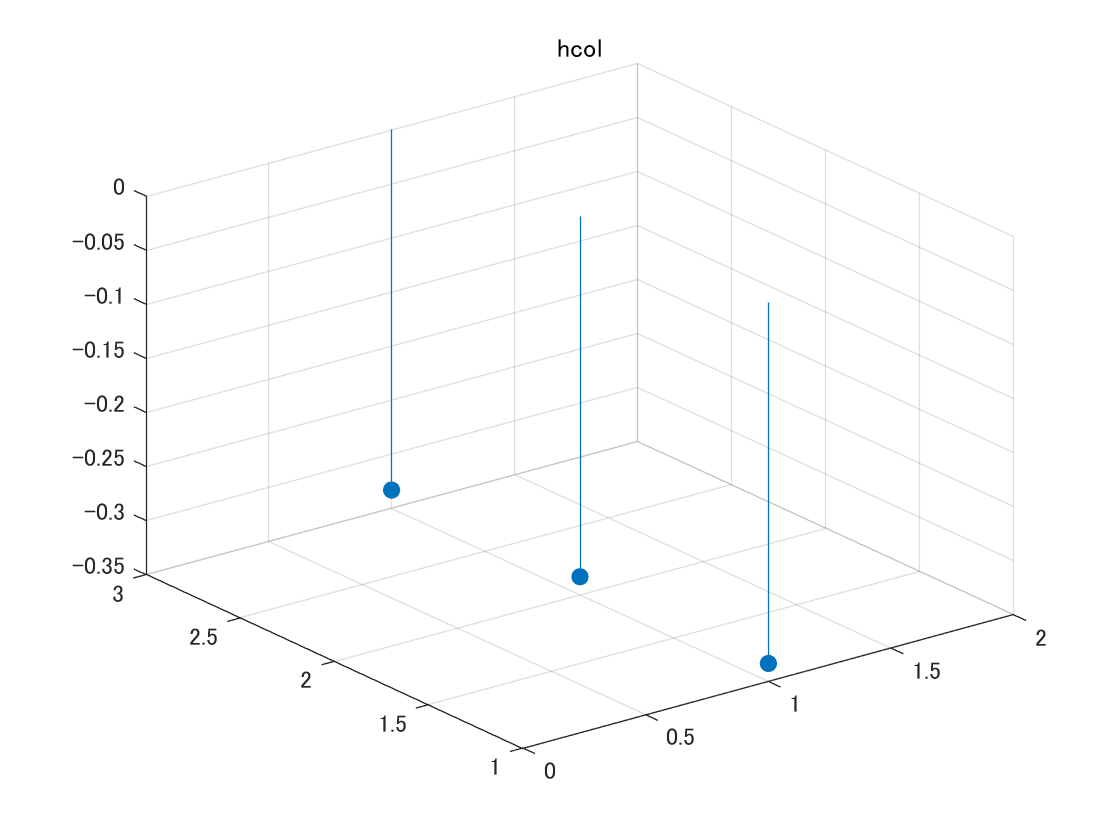

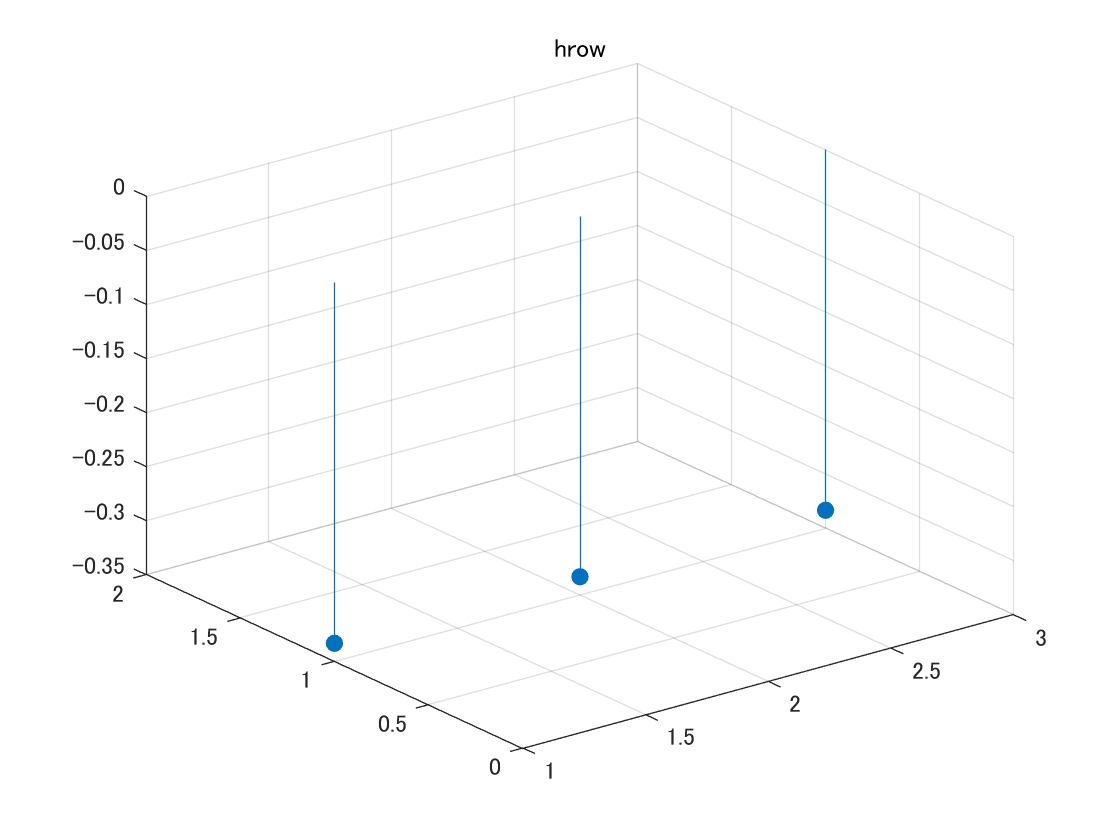

% Check if h[n] is separable
[isSeparable, hCol, hRow] = isfilterseparable(h);

% Display the result
if isSeparable
    disp('h[n] is separable.')
    disp('hcol: ')
    disp(hCol)
    disp('hrow: ')
    disp(hRow)
    figure(2)
    stem3(hCol,'filled')
    title('hcol')
    figure(3)
    stem3(hRow,'filled')
    title('hrow')
else
    disp('h[n] is not separable.')
end

#### 関数RANKによる可分離性の確認と特異値分解(SVD)

(Checking the separability using the function RANK and singular value decomposition (SVD).)

2変量のインパルス応答の可分離性は，行列 $\mathbf{H}$としてみたときの階数（非ゼロ特異値の数） $\mathrm{rank}(\mathbf{H})$ によって確認できる．(The separability of the bivariate impulse response can be checked by the rank (number of non-zero singular values) $\mathrm{rank}(\mathbf{H})$ when viewed as a matrix $\mathbf{H}$.

階数 $\mathrm{rank}(\mathbf{H})$ が１ならば可分離であり，それ以上であれば非可分である．(If the rank $\mathrm{rank}(\mathbf{H})$ is 1, it is separable; if it is higher, it is non-separable.)

インパルス応答の単変量への分解は特異値分解(SVD)によって実現できる．(The decomposition of the impulse response into univariates can be achieved by singular value decomposition (SVD).)

　　
$$\mathbf{H} = \left(\sqrt{\sigma_1}\mathbf{u}\right)\left(\sqrt{\sigma_1}\mathbf{v}\right)^T,$$


ここで $\sigma_1$は行列 $\mathbf{H}$の唯一の特異値， $\mathbf{u}$と $\mathbf{v}$ はそれぞれ左特異ベクトルと右特異ベクトルである．(where $\sigma_1$ is the only singular value of the matrix, and $\mathbf{u}$ and $\mathbf{v}$ are the left and right singular vectors, respectively.)

% Check if h[n] is separable
isRankUnique = (rank(h) == 1);

% Display the result
if isRankUnique
    [U,S,V] = svd(h,'econ');
    disp('h[n] is separable.')
    disp('sigma1^(1/2)u: ')
    disp(sqrt(S(1,1))*U(:,1))
    disp('sigma1^(1/2)v^T: ')
    disp(sqrt(S(1,1))*V(:,1).')
else
    disp('h[n] is not separable.')
    disp(['Rank of h is ' num2str(rank(h)) '.'])
end

h[n] is separable.


sigma1^(1/2)u: 


   -0.3333
   -0.3333
   -0.3333



sigma1^(1/2)v^T: 


   -0.3333   -0.3333   -0.3333



### 2変量線形シフト不変システムとしてのインパルス応答の確認

(Confirmation of impulse response as a bivariate linear shift-invariant system)

hsep =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


MSE: 5.5852e-33


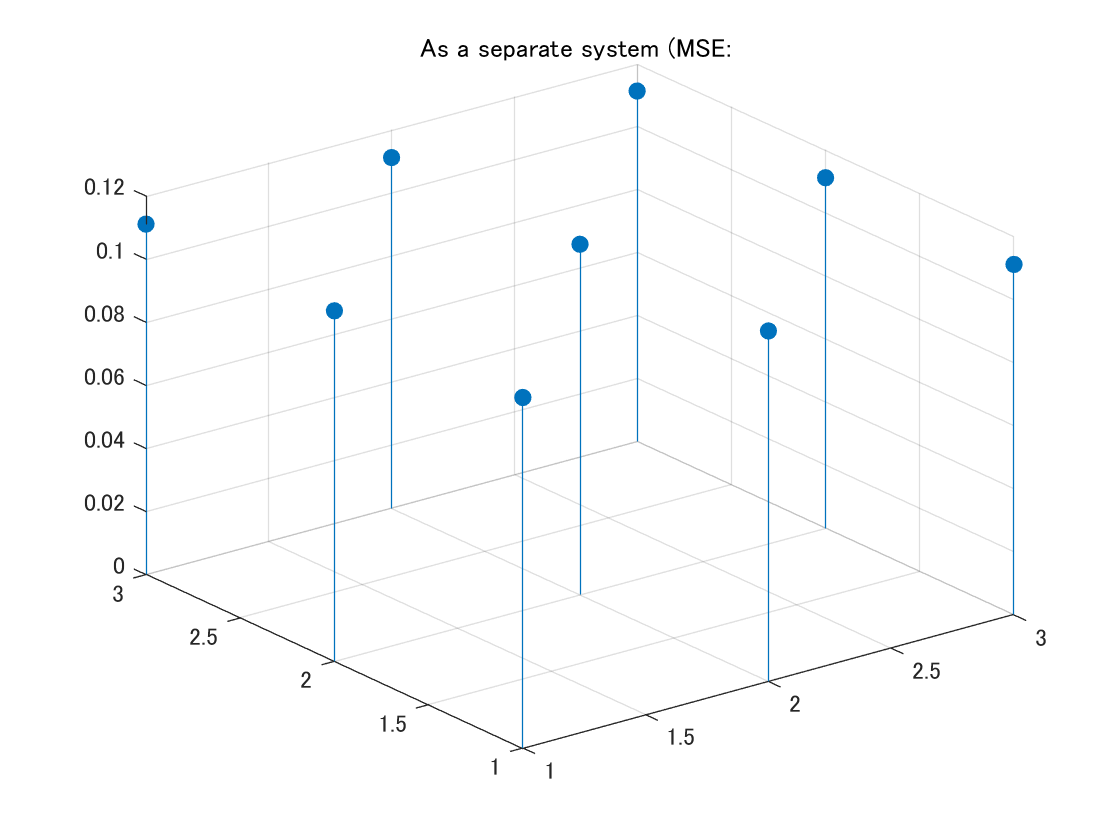

% Bivariate impulse signal
if isSeparable
    D = 1;
    hsep = imfilter(imfilter(D,...
        hCol,'conv','full'),...
        hRow,'conv','full')
    % Evaluation
    disp(['MSE: ' num2str(mse(h,hsep))] )
    figure(4)
    stem3(hsep,'filled')
    title(['As a separate system (MSE: ' mse(h,hsep) ')'])
end

### クロネッカーテンソル積による2変量インパルス応答

(Bivariate Impulse Response by Kronecker Tensor Product)

可分離フィルタはクロネッカーテンソル積でも表現できる．

(The separable filter can also be represented as a Kronecker tensor product.)

        
$$\mathbf{H} = \mathbf{h}_\mathrm{col}\otimes\mathbf{h}_\mathrm{row},$$


% Bivariate impulse signal
if isSeparable
    D = 1;
    hkron = kron(hCol,hRow)
    % Evaluation
    disp(['MSE: ' num2str(mse(h,hkron))] )
end

hkron =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


MSE: 5.5852e-33


### 分離処理による画像フィルタリング

(Image filtering by separate processing)

サンプル画像の読み込み (Reading a sample image)

% Reading image 'cameraman.tif' as double type.
I = im2double(imread('cameraman.tif'));
figure(5)
subplot(2,2,1)
imshow(I)
title('(a) Original')

IMFILTER による通常処理 (Normal processing by IMFILTER)

% IMFILTER w normal process
J = imfilter(I,h);
if min(J(:)) < 0
    J = J + .5;
end
subplot(2,2,3)
imshow(J)
title('(c) Normal ')

IMFILTERによる分離処理 (Separate processing by IMFILTER)

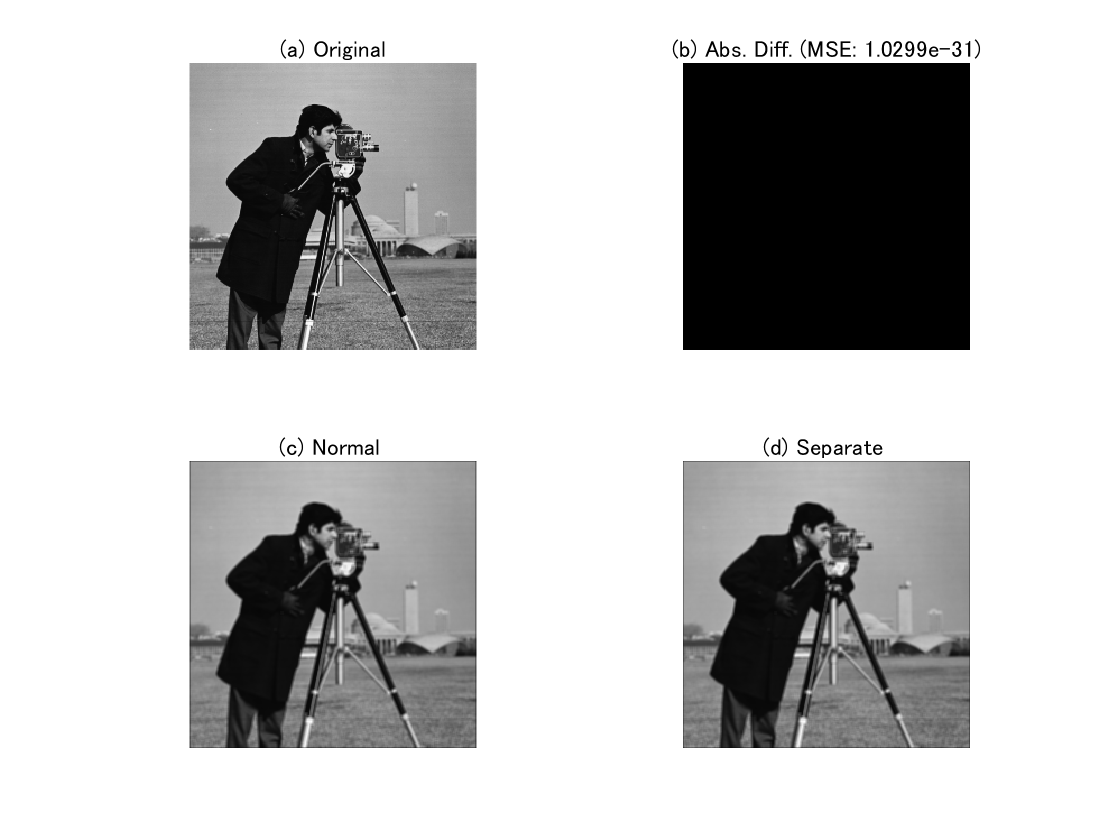

if isSeparable
    % IMFILTER w separate process
    K = imfilter(imfilter(I,hCol),hRow);
    if min(J(:)) < 0
        K = K + .5;
    end
    subplot(2,2,4)
    imshow(K)
    title('(d) Separate ')
    
    % Evaluation 
    L = imabsdiff(J,K);
    subplot(2,2,2)
    imshow(L)
    title(['(b) Abs. Diff. (MSE: ' num2str(mse(K,J)) ')'])
else
    subplot(2,2,2)
    imshow(checker_board(2,8))
    title(['(b) ' char(ftype) ' filter is non-separable.'])
    subplot(2,2,4)
    imshow(checker_board(2,8))
    title(['(d) ' char(ftype) ' filter is non-separable.'])
end

© Copyright, Shogo MURAMATSU, All rights reserved.